J = 0.02;
b = 0.1;
K = 0.01;
R = 1;
L = 0.2;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2)

P_motor =
 
             0.01
  ---------------------------
  0.004 s^2 + 0.04 s + 0.1001
 
Continuous-time transfer function.



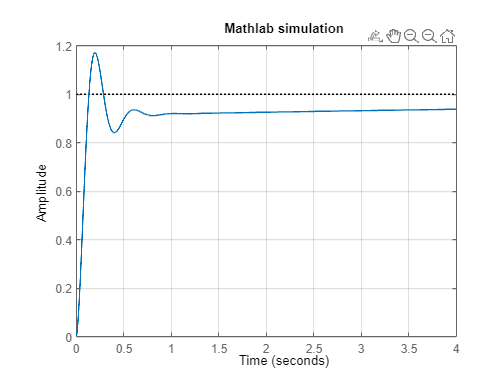

Kp = 100;
Ki = 10;
Kd = 1;
C = pid(Kp,Ki,Kd);
sys_cl = feedback(C*P_motor,1);
step(sys_cl, 0:0.01:4)
grid
title('Mathlab simulation')

motor_ss =
 
  A = 
          x1     x2
   x1    -10      1
   x2  -0.02     -2
 
  B = 
       u1
   x1   0
   x2   2
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.

